# Dekorelacja informacji wektorowej

Wczytuje pliki *mix1 *i *mix2*

clear all
mix1 = audioread("dzwiek/mix1.wav");
mix2 = audioread("dzwiek/mix2.wav");

buduje macierz kowariancji *cov()*

mix12cov = cov(mix1,mix2);

obliczam wektory wlasne macierzy `mix12cov, `w wyniku dostajac `[V,D] `gdzie V jest `eigenvector` a D: `eigenvalues.`

[V,D] = eig(mix12cov);

mnoze macierz wektorow wlasnych z danymi wejsciowymi

unmixed = V'*[mix1 mix2]';

wykresy przed i po (widac brak korelacji na drugim):

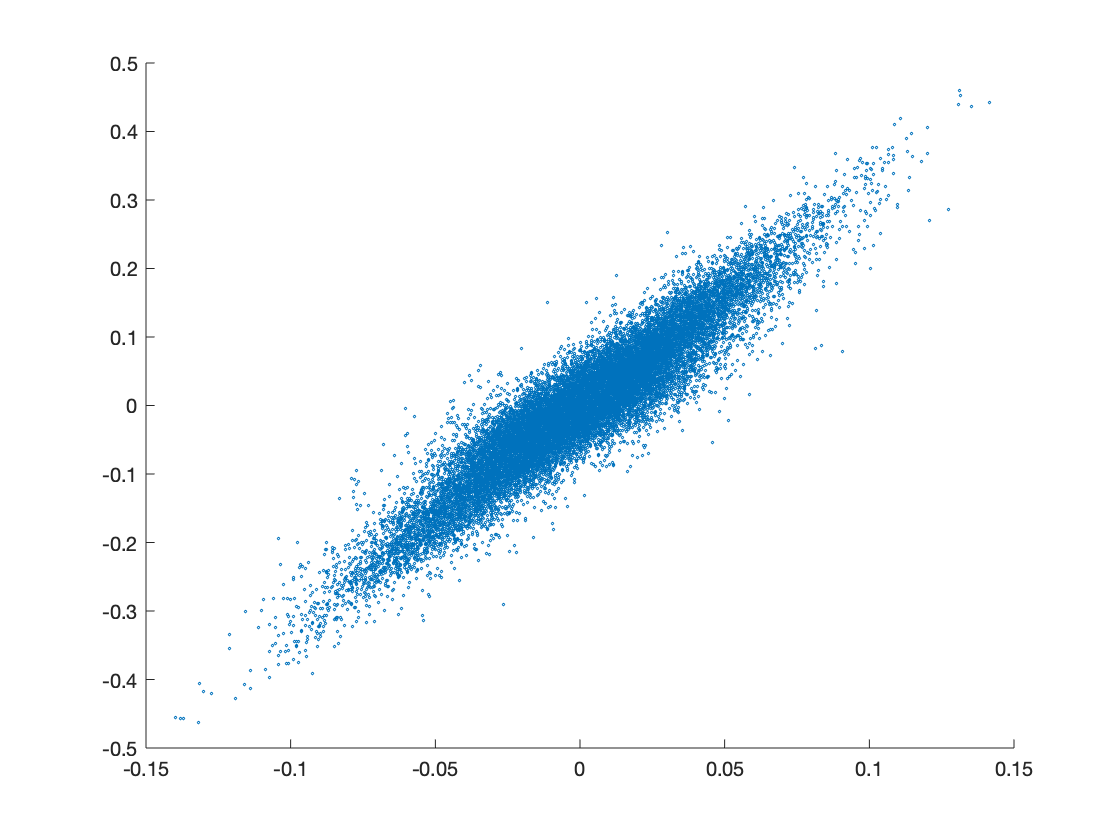

scatter(mix1(1:10:end),mix2(1:10:end),2)

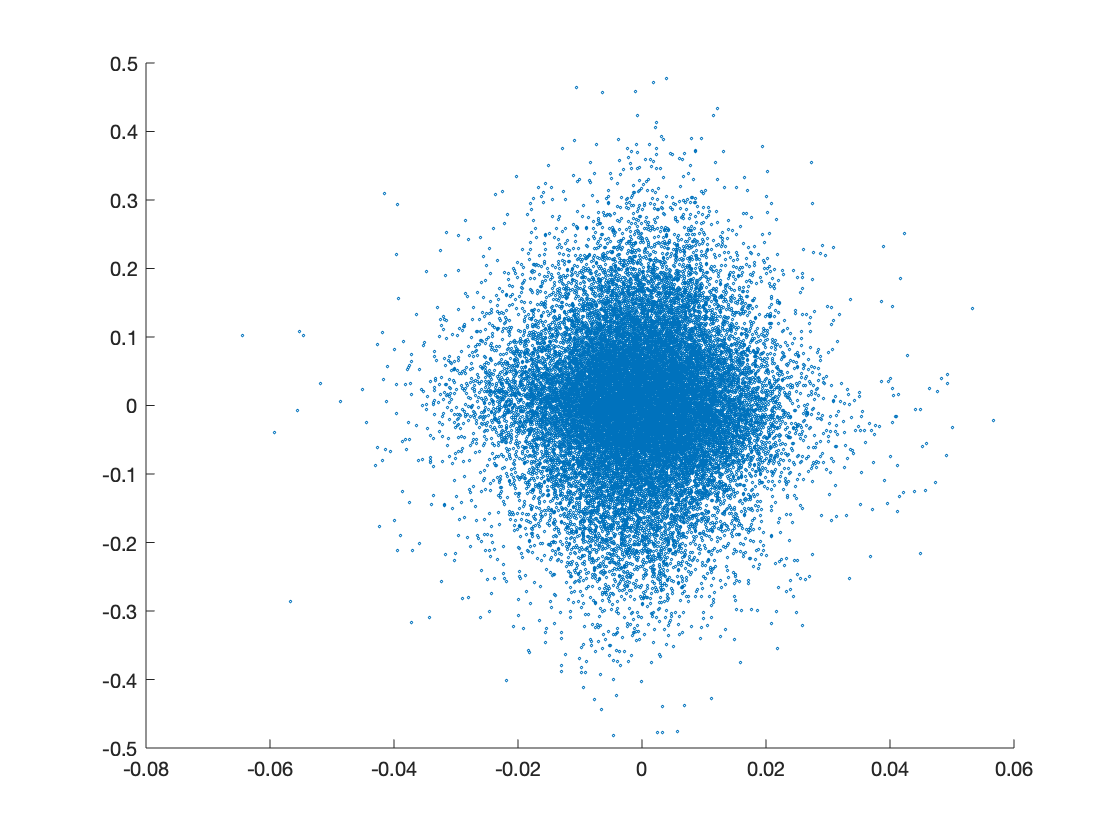

scatter(unmixed(1,1:10:end),unmixed(2,1:10:end),2)

zapisanie do pliku z  `freq=sample_rate/dlugosc`

audiowrite('unmixed.wav',unmixed(2,:),16815)

## Dwa sygnaly wlasne:

dwa sygnaly: jeden pozbawiony 2 czestotliwosci sinusoidalnych

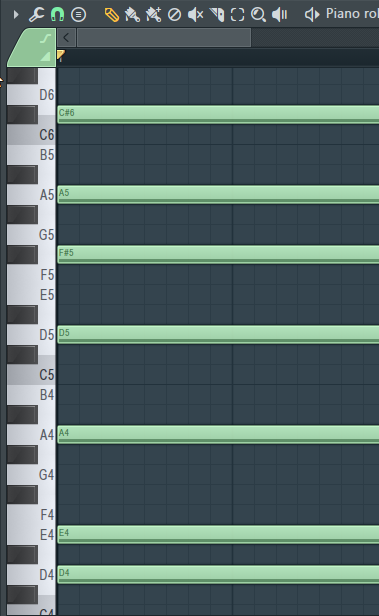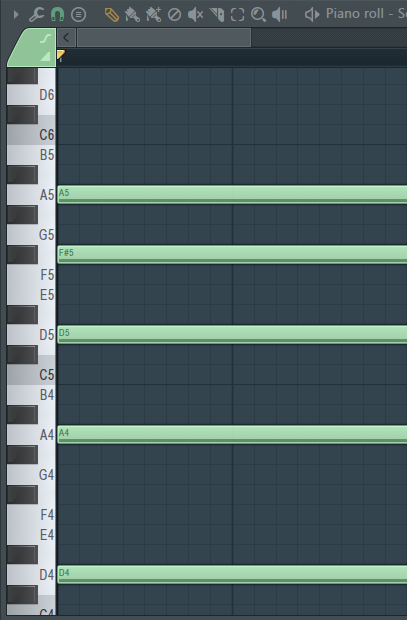

my_mix1 = audioread("m1_gen.wav");
my_mix2 = audioread("m2_gen.wav");

wykresy:

figure(2)
plot(my_mix1(1:end/100,1))

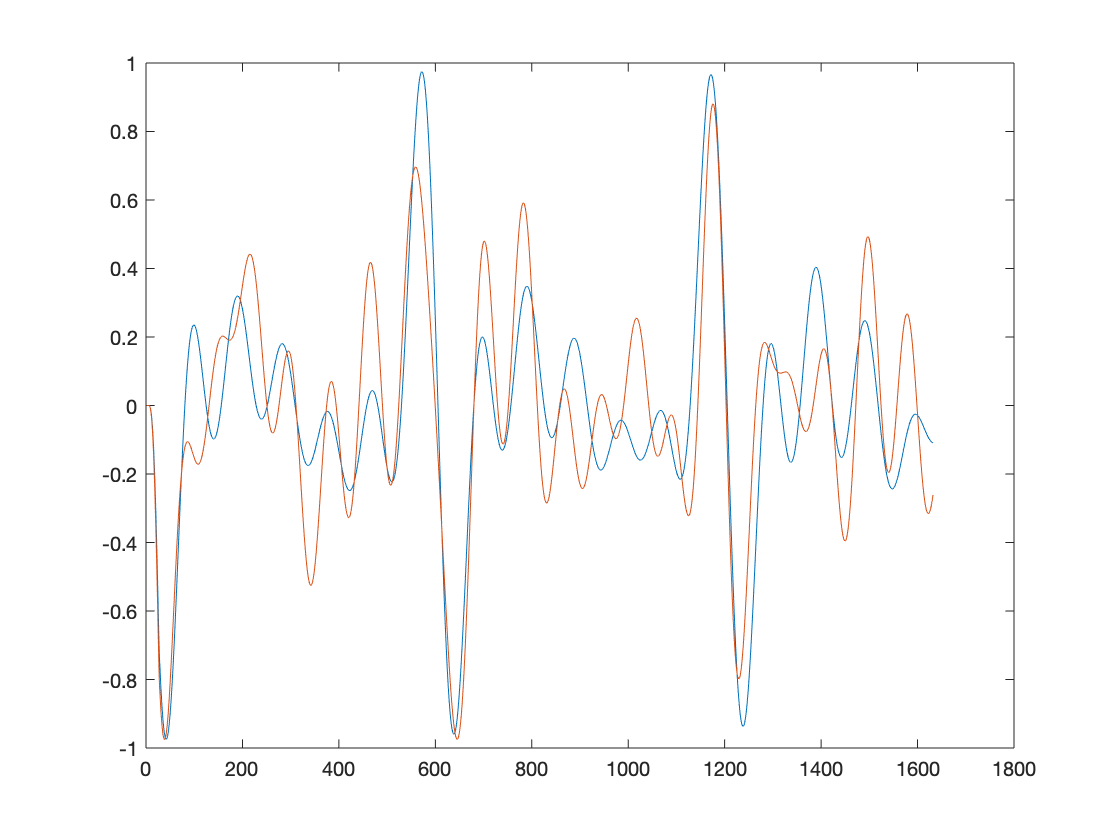

hold on
plot(my_mix2(1:end/100,1))

kod analogiczny jak w poprzedniej czesci

my_mix12cov = cov(my_mix1,my_mix2);
[my_V,my_D] = eig(my_mix12cov);
my_unmixed = my_V'*[my_mix1(:,1) my_mix2(:,1)]';
audiowrite('my_unmixed.wav',my_unmixed(2,:),16000)

## Kolejne dwa sygnaly wlasne: 

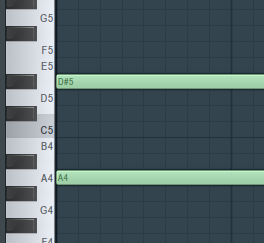

my_mix12 = audioread("m1_gen2.wav");
my_mix22 = audioread("m2_gen2.wav");

wykresy

figure(3)
plot(my_mix12(1:end/100,1))

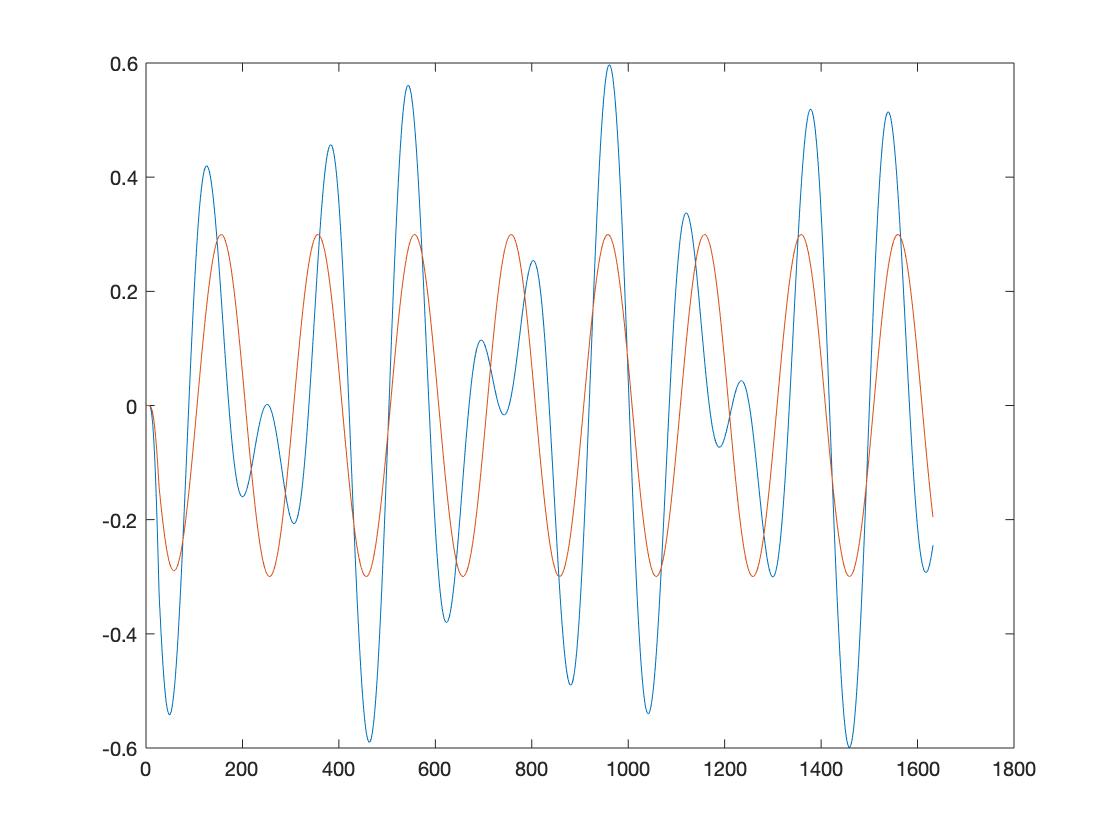

hold on
plot(my_mix22(1:end/100,1))

reszta analogiczna

my_mix12cov2 = cov(my_mix12,my_mix22);
[my_V2,my_D2] = eig(my_mix12cov2);
my_unmixed2 = my_V2'*[my_mix12(:,1) my_mix22(:,1)]';
audiowrite('my_unmixed2.wav',my_unmixed2(2,:),16000)